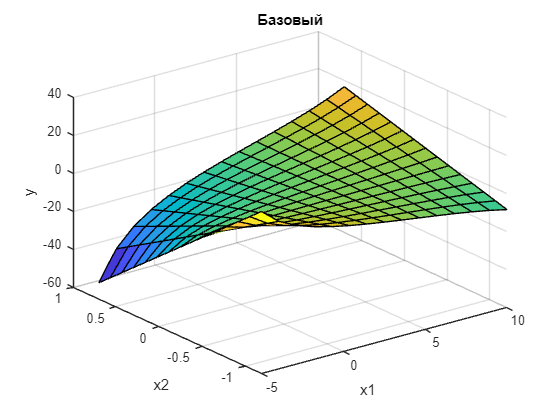

% Определение входных переменных
n = 15;
x1 = linspace(-5, 10, n); % x1 ∈ [-5, 10]
x2 = linspace(-1.2, 0.7, n); % x2 ∈ [-1.2, 0.7]

figure;
y1 = zeros(n,n);
for i=1:n
 for j=1:n
 y1(i,j) = 2 * x1(i) * tan(x2(j));
 end
end
surf(x1,x2,y1);
xlabel('x1');
ylabel('x2');
zlabel('y');
title('Базовый');
grid on;

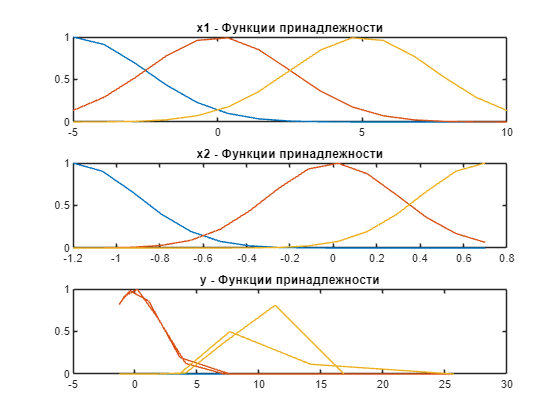


% Оценка функции
y = 2 * x1 .* tan(x2);

% Задание функций принадлежности для входных переменных с использованием гауссиан
x1_low = gaussmf(x1, [2.5, -5]);
x1_medium = gaussmf(x1, [2.5, 0]);
x1_high = gaussmf(x1, [2.5, 5]);

x2_low = gaussmf(x2, [0.3, -1.2]);
x2_medium = gaussmf(x2, [0.3, 0]);
x2_high = gaussmf(x2, [0.3, 0.7]);

% Определение функций принадлежности для выходной переменной
y_low = gaussmf(y, [2, -10]);
y_medium = gaussmf(y, [2, 0]);
y_high = gaussmf(y, [2, 10]);

% Вывод графиков функций принадлежности
figure;
subplot(3,1,1);
plot(x1, x1_low, x1, x1_medium, x1, x1_high);
title('x1 - Функции принадлежности');

subplot(3,1,2);
plot(x2, x2_low, x2, x2_medium, x2, x2_high);
title('x2 - Функции принадлежности');

subplot(3,1,3);
plot(y, y_low, y, y_medium, y, y_high);
title('y - Функции принадлежности');

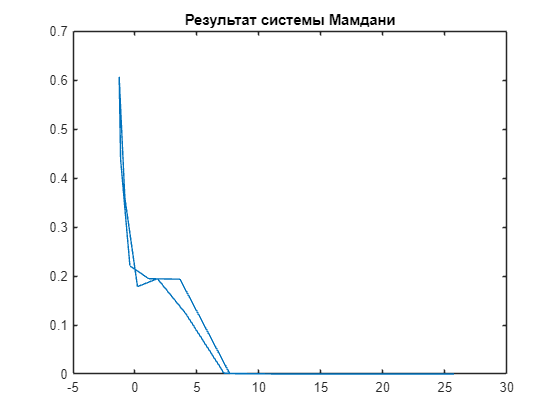


% Вывод правил (произведение функций принадлежности для каждой пары правила)
rule1 = min(x1_low, x2_low);
rule2 = min(x1_medium, x2_medium);
rule3 = min(x1_high, x2_high);

% Комбинирование правил
agg_rule = max(max(rule1, rule2), rule3);

% Дефаззификация для определения выходного значения
output = max(min(y_low, agg_rule), min(y_medium, agg_rule));

% Вывод графика результата
figure;
plot(y, output);
title('Результат системы Мамдани');

fuzzyLogicDesigner();